# Variational Autoencoder (VAE) pre-trained on MNIST images

We will be working with a variational autoencoder (VAE) networkthat has been pre-trained to reconstruct 28x28 pixel images of handwritten digits.

## SECTION 1: Load Trained VAE network

We will load in a VAE network that has already been trained on 54,000 examples of handwritten digits 1-9; NO EXAMPLES OF THE DIGIT '0' WERE INCLUDED IN THE TRAINING SET, so this trained network has never seen a zero before. The VAE network feeds MNIST images through an encoder, then squeezes the image representation through a 'bottleneck' of 10 latent variables; the latent variable values then pass through a decoder that reconstructs the original image. The autoencoder architecture looks like this:

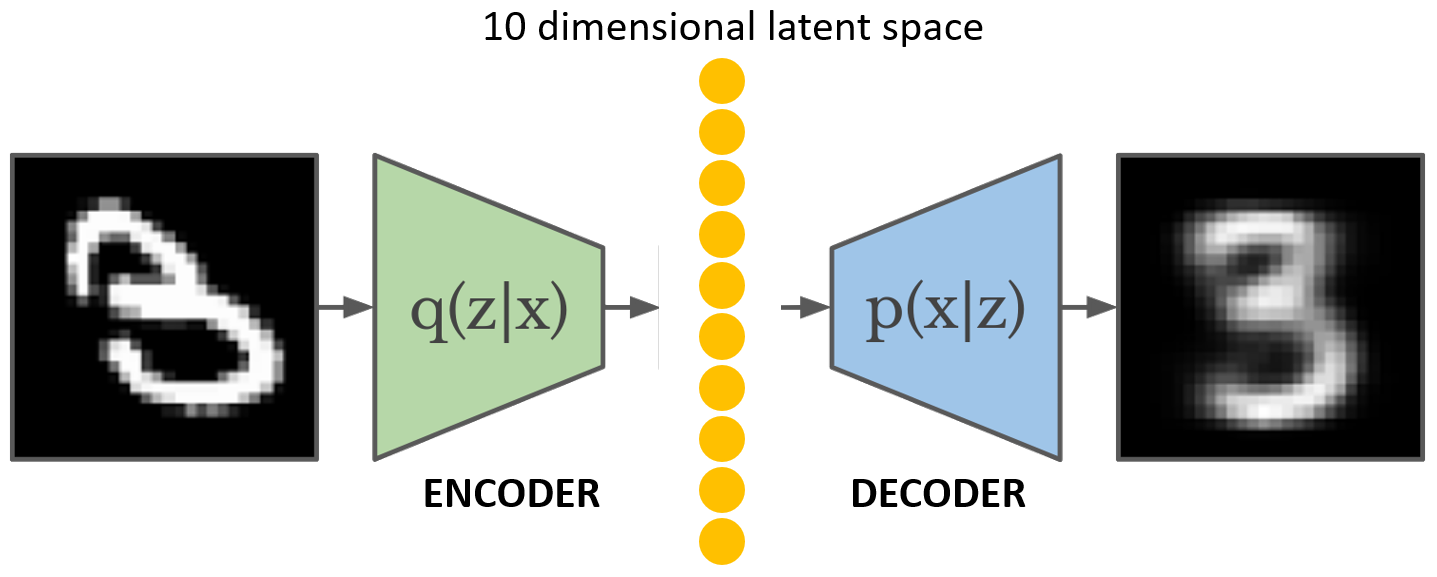  

A more detailed diagram of the VAE looks like:

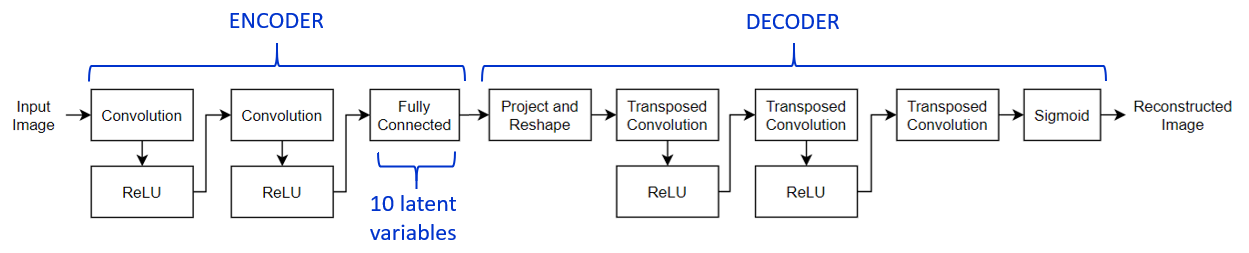

The encoder stage consists of two sequential convolutional layers that extract feature maps, followed by a fully connected layer, followed by an "image encoding" layer which is the 10-unit latent variable layer:

- The first convolution layer contains 32 feature maps and uses stride=2 

- The second convolution layer contains 64 feature maps and uses stride=2

- The fully connected layer contains the 10-element feature vector 

The decoder stage consists of two sequential deconvolution layers (deconvolution is the mathematical opposite of convolution!) followed by transposition back to the 28x28 image plane:

- The first deconvolution layer contains 64 feature maps and uses stride=2 

- The second convolution layer contains 32 feature maps and uses stride=2

- The output is a 28x28 grayscale image

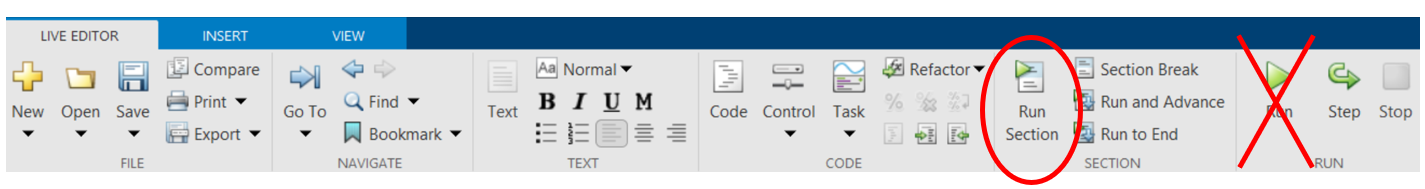

To read in the trained model,  click inside of the code block below then click 'Run Section' under the 'Live Editor' tab menu. IT MAY TAKE SOME TIME FOR THE MODEL TO LOAD SO BE PATIENT.

clear all; % clear all workspace variables

clf;

% set working directory to 'userpath' if it exists
if exist('userpath')
    workingfolder=['C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB'];
else % otherwise use current directory
    workingfolder=pwd;
end

SIDfile; 

numLatentChannels = 10; % the VAE has 10 latent feature variables

load 'VAEnet_drop0_features10'; %read in the trained network

trainImagesFile = "train-images-idx3-ubyte.gz"; %load 60,000 MNIST training images (digits 0-9)
XTrain = processImagesMNIST(trainImagesFile); % extract training images


Read MNIST image data...
Number of images in the dataset:  60000 ...



testImagesFile = "t10k-images-idx3-ubyte.gz";   %load 10,000 MNIST testing images (digits 0-9)
XTest = processImagesMNIST(testImagesFile); %extract testing images


Read MNIST image data...
Number of images in the dataset:  10000 ...



% format the 10,000 test input images of digits 0-9 (stored in 'XTest') to be fed through the VAE and
% reconstructed at the network's output
dsTest = arrayDatastore(XTest,IterationDimension=4);
numOutputs = 1;
mbqTest = minibatchqueue(dsTest,numOutputs, ...
    MiniBatchSize = size(XTest,4), ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB");

% Open and read the file containing labels for the training images 
fileId = fopen('train-labels-idx1-ubyte', 'r', 'b'); % 'b' for big-endian
magicNum = fread(fileId, 1, 'int32');   % Read the magic number
numLabels = fread(fileId, 1, 'int32');  % Read the number of labels
trainlabels = fread(fileId, numLabels, 'uint8'); % Read the labels
fclose(fileId); % Close the file

% Open and read the file containing labels for the testing images 
fileId = fopen('t10k-labels-idx1-ubyte', 'r', 'b'); % 'b' for big-endian
magicNum = fread(fileId, 1, 'int32');
numLabels = fread(fileId, 1, 'int32');
testlabels = fread(fileId, numLabels, 'uint8');
fclose(fileId);

% Feed XTest images through the network and store reconstructed output
% images in 'YTest'
YTest = modelPredictions(netE,netD,mbqTest);

## QUESTION 1: Generate image of a '5' from a latent vector

To generate novel images using the VAE, we can input latent vectors to the decoder and it will convert them into digit images:  

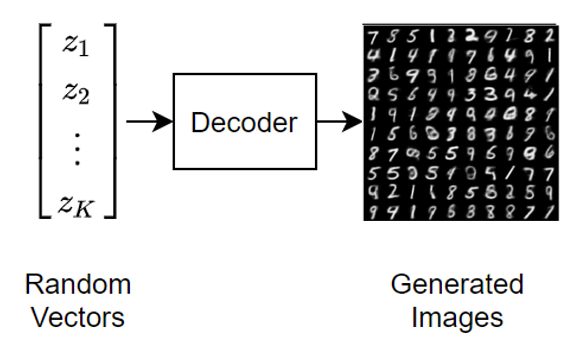

The code below generates a single digit image from ten latent vector values. The latent values are currently set to be all zeros, which generates the canonical '8' image. 

By setting the 10 latent values to numbers ranging between -3 and 3, try to find a set of values that generates a good image of a '5'; you can hit 'Run Section' to view the output digit after setting the vector values to your liking. 

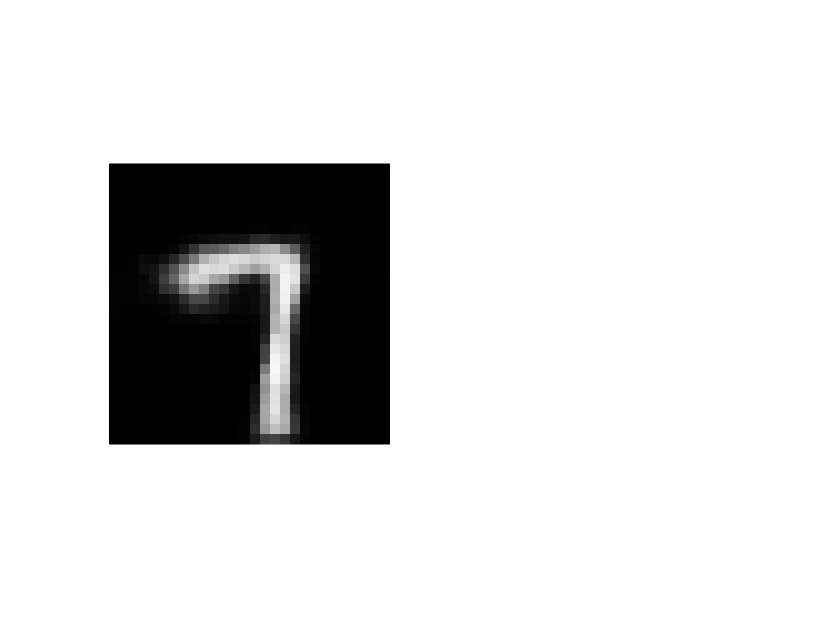


%generate 10,000 random digits from random latent vectors
ZNew = [-3; 2; -1; 0; 0; 0; 0; 0; 0; 0];
answer.q1=ZNew;
ZNew = dlarray(ZNew,"CB");
YNew = predict(netD,ZNew);
YNew = extractdata(YNew);
subplot(1,2,1);
imshow(YNew)

## SECTION 2: Generate digits from random latent vectors

The code below generates 10,000 digit images by feeding random latent vectors into the VAE decoder. The VAE was trained only on the digits 1-9, not 0.  

Each randomly generated digit from the output of the decoder is fed as input to a pattern classifer network (similar to LeNet) that classifies the generated image as a digit 0-9 (note that unlike the VAE that was trained only on digits 1-9, the pattern classifer was trained on all digits 0-9, so that it can recognize any any digit including 0). When you run the code below, it will show the first 100 randomly generated digits (out of 10,000), and bar graph showing what percentage of generated images were classified as each digit. Use the output from this code to answer question 2 below. 

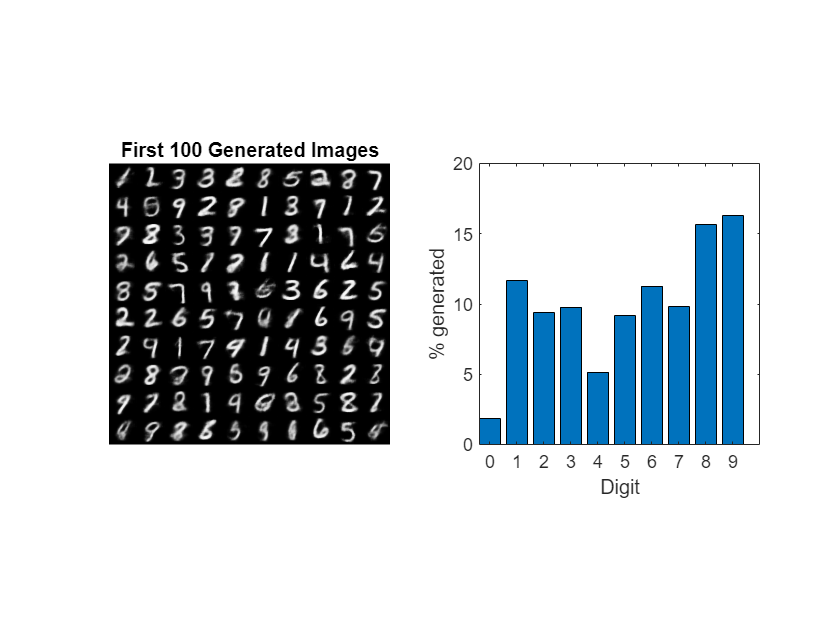

%generate 10,000 random digits from random latent vectors
numImages = 10000;
ZNew = randn(numLatentChannels,numImages);
ZNew = dlarray(ZNew,"CB");
YNew = predict(netD,ZNew);
YNew = extractdata(YNew);

%display the first 100 randomly generated digits
figure
subplot(1,2,1);
I = imtile(YNew(:,:,:,1:100));
imshow(I)
title("First 100 Generated Images")

% load in a trained CNN to classify the randomly generated digits, plot a
% bar graph to show the percentage of random digits that belong to classes
% 0-9
load 'mnistCNN';
YPred = classify(mnistCNN,YNew);
for i=0:9
    ndig(i+1)=sum(double(YPred)==(i+1));
end
subplot(1,2,2);
bar(0:9,100*ndig/sum(ndig));
xlabel('Digit');
ylabel('% generated');
axis square;

## QUESTION 2: Digit generation 

PART A: Based upon the results from Section 2, which digit was most likely to be generated from a random latent vector?

answer.Q2a = 9; 

PART B: Based upon the results from Section 2, which digit was least likely to be generated from a random latent vector?

answer.Q2b = 0; 

## SECTION 3: Compare reconstruction error for the digits 0-9

The code below feeds 10,000 test images to the input of the VAE (different from the training set), and plots a bar graph of the mean and standard deviation of the MSE reconstruction error for examples of the digits 0-9. Remember, this VAE network has only been trained on the digits 1-9. It was not trained on 0. 

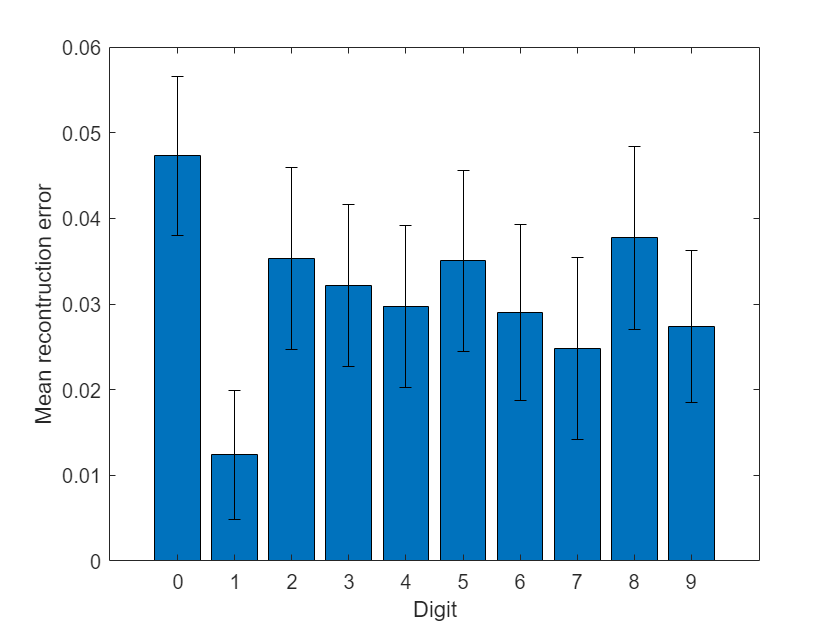

msqerr = []; % empty the variable for gathering MSE error scores
for l=0:9  % loop through the digits 0-9
    dex=find(testlabels==l); % isolate test images of the currently selected digit
    sqerr = squeeze((XTest(:,:,:,dex)-YTest(:,:,:,dex)).^2); % compute squared error of each pixel in each image
    msqerr = [msqerr squeeze(mean(mean(sqerr(:,:,1:800))))]; % average over pixels in each image to compute its MSE
end

means = mean(msqerr);
stdErrors = std(msqerr) ;
figure;
b = bar(0:9,means);
hold on;
errorbar(0:9, means, stdErrors, 'k', 'LineStyle', 'none');
xlabel('Digit');
ylabel('Mean recontruction error');
hold off;

## QUESTION 3: Best and worst reconstruction error 

PART A: Based upon the results from Section 2, which digit is the VAE able to reconstruct most accurately? 

answer.Q3a = 1; 

PART B: Based upon the results from Section 2, which digit is the VAE able to reconstruct most accurately? 

answer.Q3b = 1; 

## SECTION 4: Further train the VAE network to reconstruct zeros without interleaving

Now we are going to train the VAE to reconstruct images of zeros. This will be the first time the network has ever been trained on a zero, since it was previously trained only to reconstruct digits 1-9. 

In this initial attempt, we will train the network to reconstruct 6000 examples of zero images. Each training example of a zero will be presented only once per iteraton of gradient decent; zeros will NOT be interleaved with examples of other digits; because of this, we will see that catastrophic interference occurs.

When you run the code below, a progress window will appear to show how reconstruction error is reduced over training trials. Again, only zeros (and no other digits) are being presented on every training trial. The training may take seom time, so be patient.

When the training finishes, a random set of 10,000 latent vectors will then be presented as input to the decoder side of the retrained network (as we did above in Section 2 before retraining). You will see a mosaic of the first 100 images that the retrained network generates from random vectors. 

The generated images will be fed to a pattern classifer, and a bar graph will show what percentage of generated images were classified as each digit (0-9).    

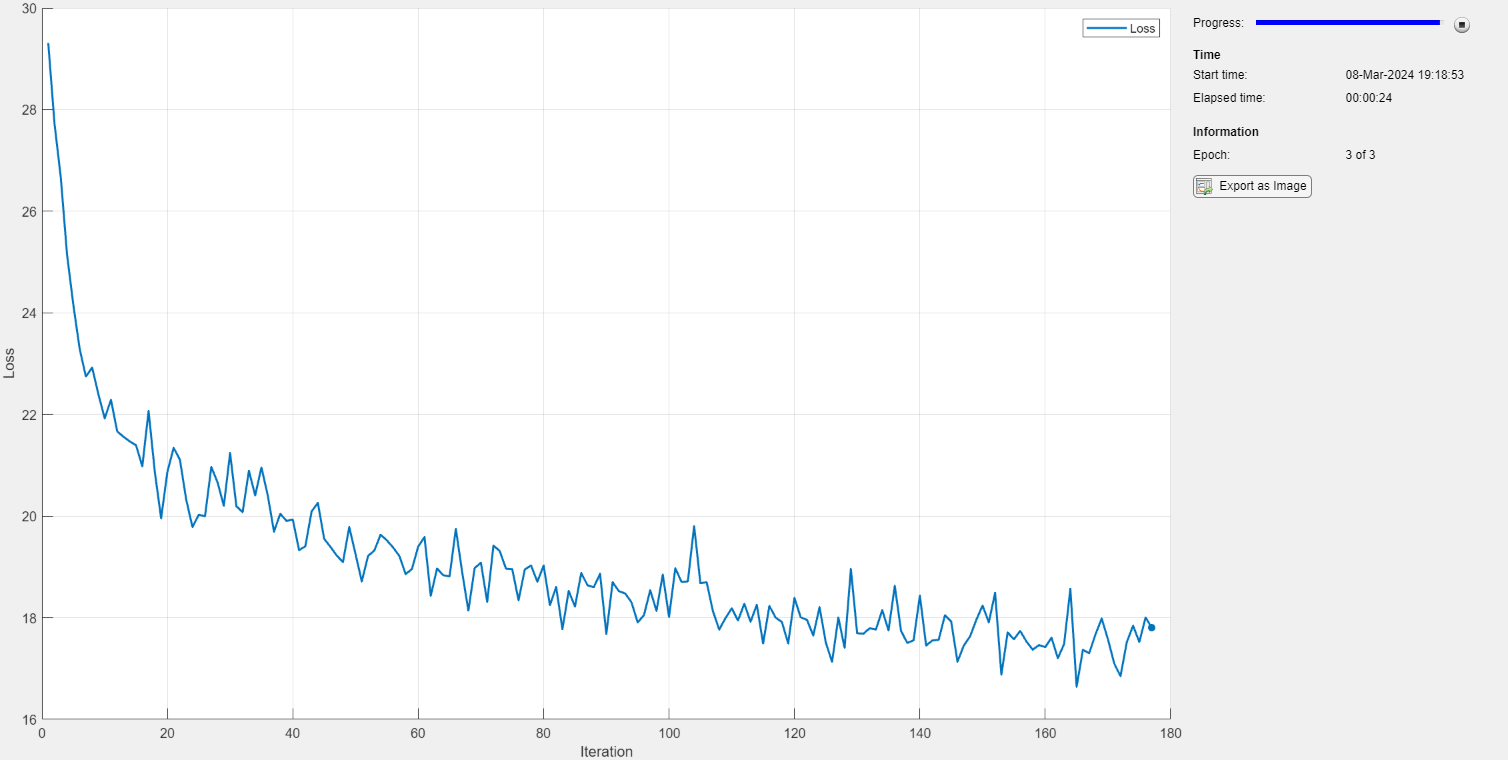

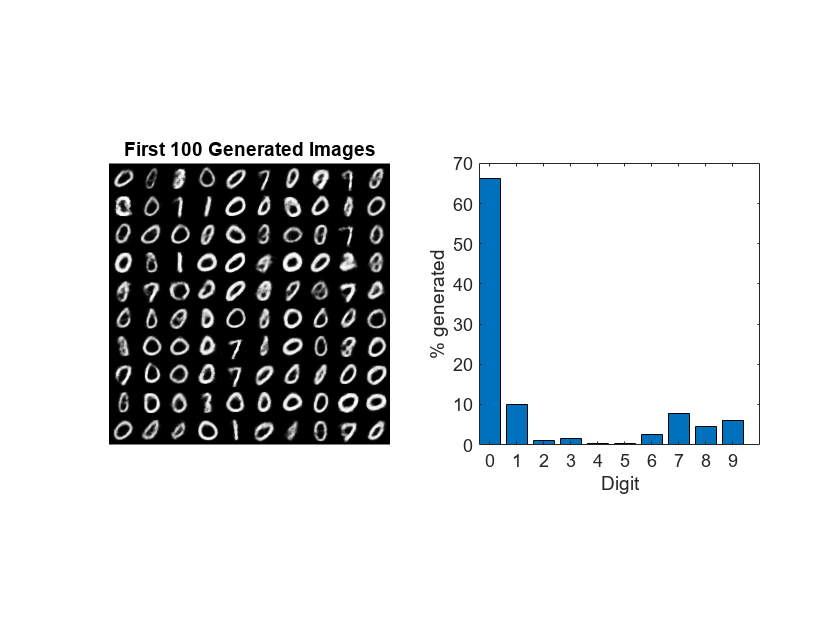

% Create a retraining dataset that contains only zeros and no other digits
dex=find(trainlabels == 0);

[newE, newD] = RetrainVAE(XTrain(:,:,:,dex),netE,netD,numLatentChannels,3);

% Feed XTest images through the network and store reconstructed output
% images in 'YTest'
shuffle(mbqTest);
YTest = modelPredictions(newE,newD,mbqTest);

## QUESTION 4: Digit generation by network retrained without interleaving

PART A: Based upon the results from Section 2, which digit was most likely to be generated from a random latent vector by the retrained network?

answer.Q4a = 0; 

PART B: Based upon the results from Section 2, which digit was least likely to be generated from a random latent vector by the retrained network (if it looks like there is tie then choose one of the numbers)?

answer.Q4b = 4; 

## SECTION 5: Train the VAE network on zeros interleaved with the entire original dataset 

Now we are again going to train the VAE to reconstruct images zeros for the first time. We will start fresh from the network that was trained on digits 1-9 but has never seen a zero, so as before, this will be the first time the network has ever been trained on a zero. 

In this second attempt, we will retrain the network on all 60,000 images in the MNIST training set, including zeros as well as all other digits (about 6000 examples of each digit). Zeros will be interleaved with all the other digits, and because of this, we will see that the network is protected from catastrophic interference.

When you run the code below, a progress window will appear to show how reconstruction error goes down over training trials. Since we are now training on all digits instead of just zeros, the training will take considerably longer, so be patient! When the training finishes, a picture of the progress window will appear below the code window, and below that, you will see a mosaic of the first 100 images that the retrained network generates from random vectors, and a bar graph showing what percentage of randomly generated digits belonged to each class (0-9).    

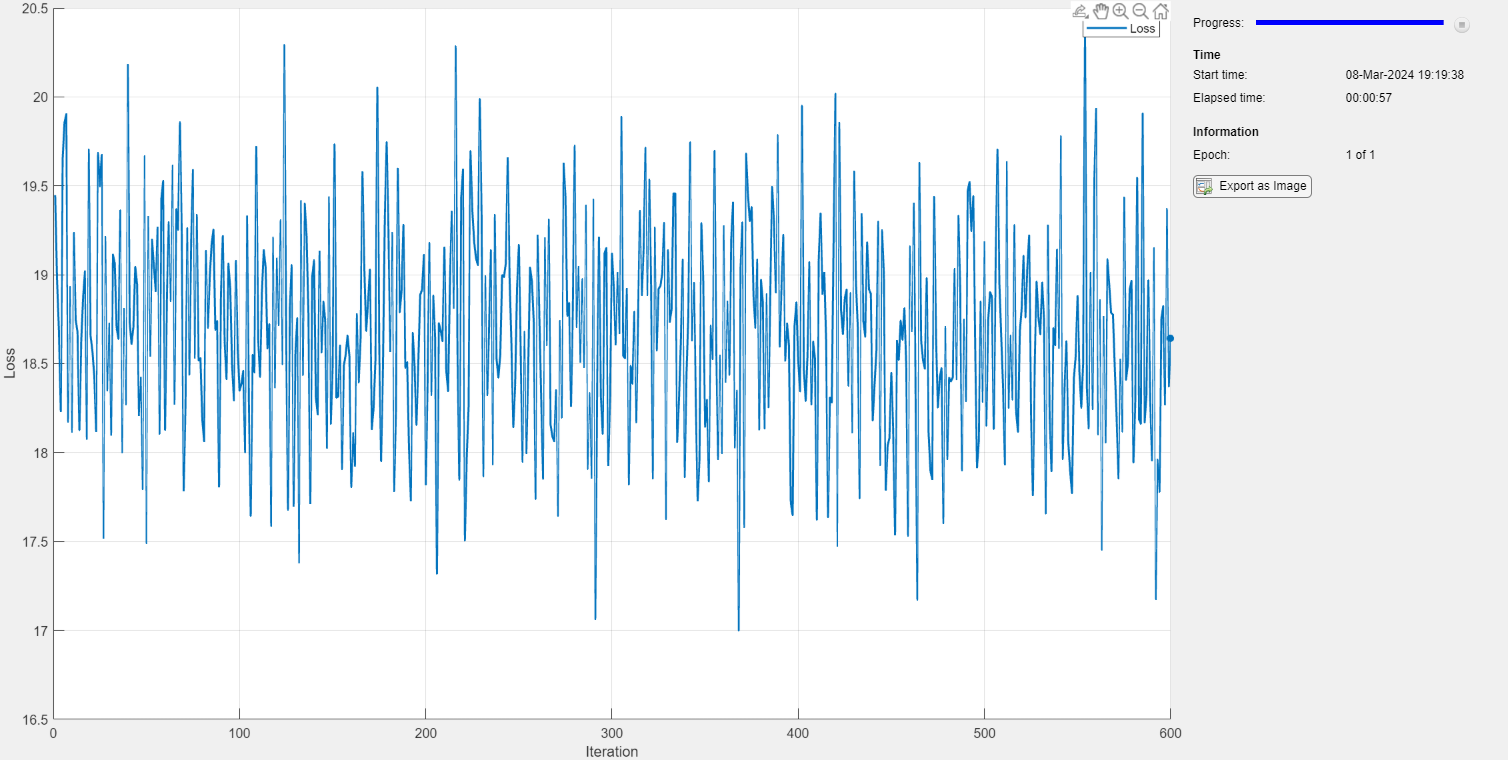

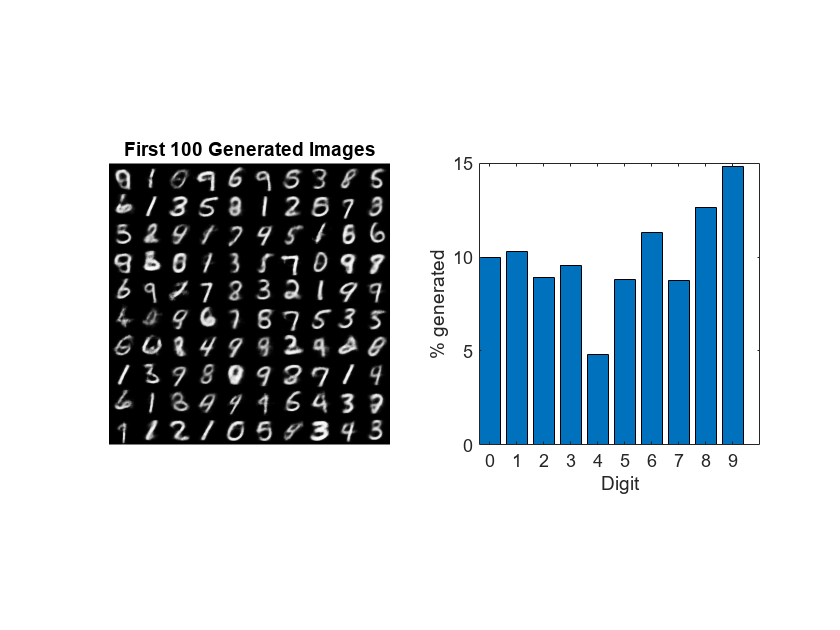


%%% retrain on excluded digit (zero) plus ALL original examples of other
%%% digits (i.e., retrain on full MIKNST dataset of 60,000 digitd 0-9)

[newE, newD] = RetrainVAE(XTrain,netE,netD,numLatentChannels,1);

## QUESTION 5: Digit generation by network retrained without interleaving

PART A: Based upon the results from Section 2, which digit was most likely to be generated from a random latent vector by the retrained network?

answer.Q5a = 9; 

PART B: Based upon the results from Section 2, which digit was least likely to be generated from a random latent vector by the retrained network (if it looks like there is tie then choose one of the numbers)?

answer.Q5b = 4; 

## SECTION 6: Train the VAE network on zeros interleaved with "dreamed" examples of other digits

We are again going to train the VAE to reconstruct images zeros for the first time. We will start fresh from the network that was trained on digits 1-9 but has never seen a zero, so as before, this will be the first time the network has ever been trained on a zero. 

In this third and final attempt, we will train the network on images of zeros (which the network has never seen before) as well the familiar digits 1-9. The difference is that we will use GENERATED rather then STORED examples of the familiar digits.  Zeros will be interleaved with "dreamed" examples of all the other digits. Will we still protection from catastrophic interference when the familiar digits are generated ("dreamed") rather than retrieved from external memory storage?

When you run the code below, a progress window will appear to show how reconstruction error goes down over training trials. Since we are now training on all digits instead of just zeros, the training will take awhile, so be patient! When the training finishes, a picture of the progress window will appear below the code window, and below that, you will see a mosaic of the first 100 images that the retrained network generates from random vectors, and a bar graph showing what percentage of randomly generated digits belonged to each class (0-9).    

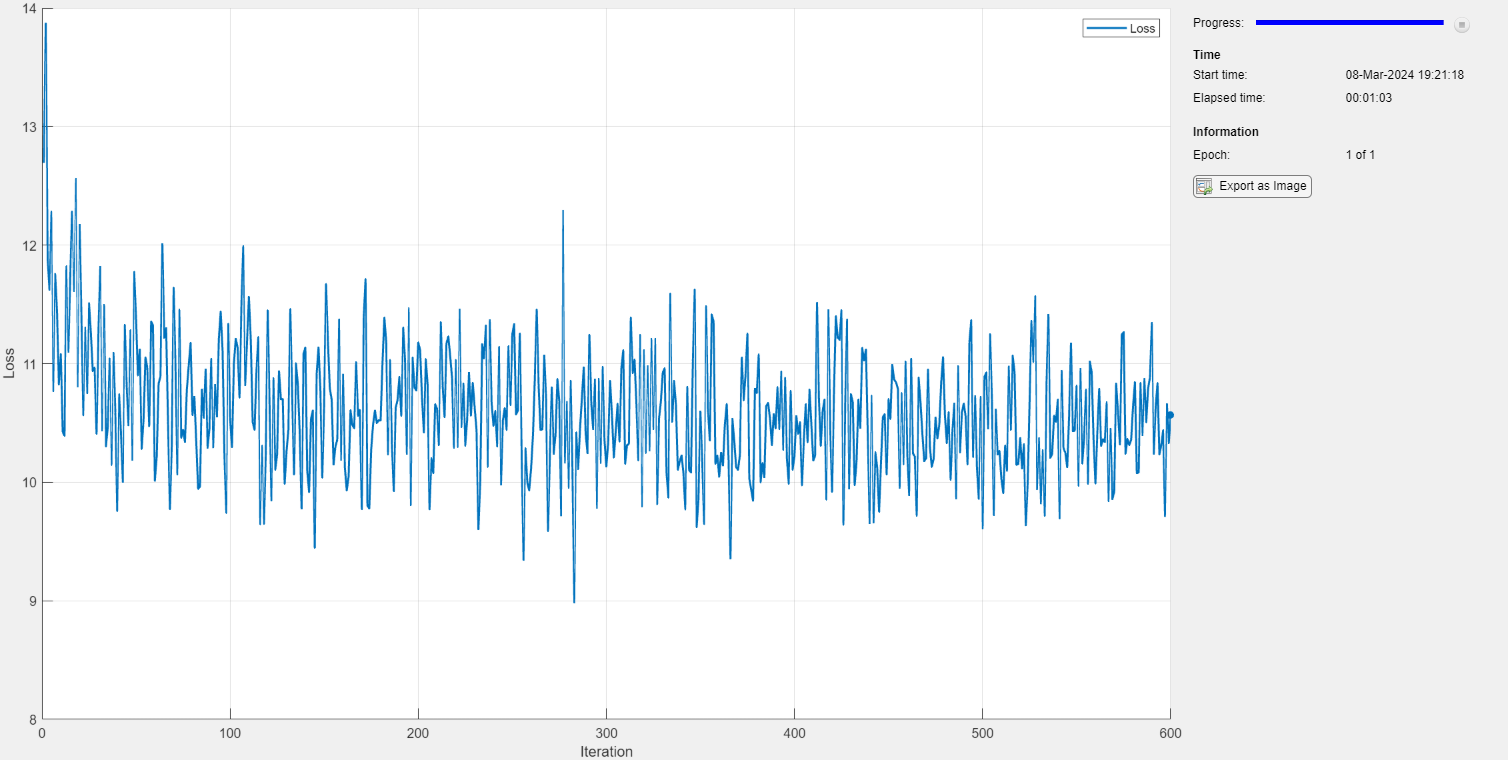

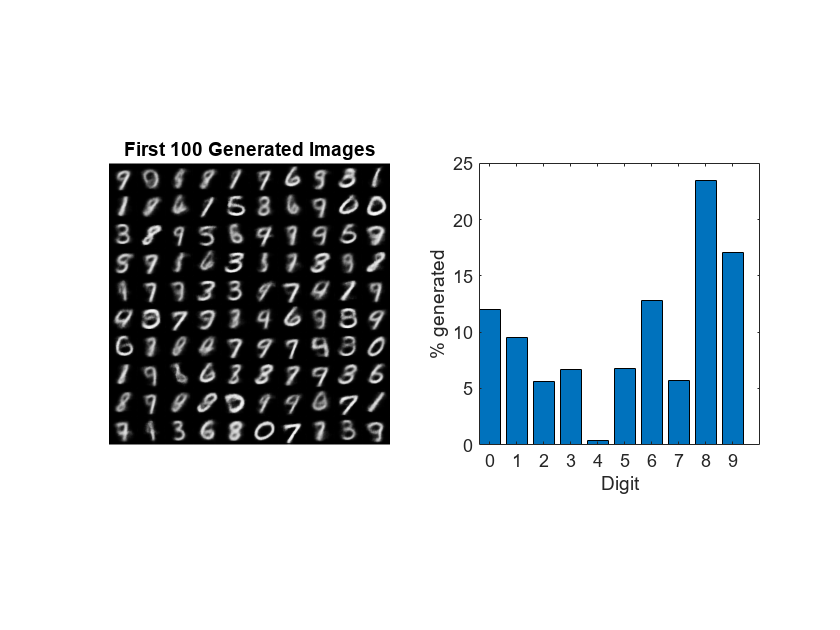

XReTrain = XTrain*0;
for i=1:10
ZNew = randn(numLatentChannels,6000);
ZNew = dlarray(ZNew,"CB");
YNew = predict(netD,ZNew);
XReTrain(:,:,:,(i-1)*6000+[1:6000]) = extractdata(YNew);
end
dex=find(trainlabels == 0);
XReTrain(:,:,:,dex)=XTrain(:,:,:,dex);

[newE, newD] = RetrainVAE(XReTrain,netE,netD,numLatentChannels,1);

## QUESTION 6: Digit generation by network retrained without interleaving

PART A: Based upon the results from Section 2, which digit was most likely to be generated from a random latent vector by the retrained network?

answer.Q6a = 8; 

PART B: Based upon the results from Section 2, which digit was least likely to be generated from a random latent vector by the retrained network (if it looks like there is tie then choose one of the numbers)?

answer.Q6b = 4; 

## SECTION 7: Save and submit your assignment

When you run the code below, your results from this exercise will be saved to a file called '123456789_assignment7' (where 123456789 is your student ID number). Upload this file to Canvas to submit your assignment. 

% SAVE FILE TO SUBMIT ON CANVAS
filename = [num2str(SID) '_assignment7'];
save(['C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB/' filename],'answer');
    

## -----------------------YOU DO NOT NEED TO BE CONCERNED WITH ITEMS BELOW THIS LINE-------------------------

## Helper Functions

### Model Loss Function

The `modelLoss` function takes as input the encoder and decoder networks and a mini-batch of input data, and returns the loss and the gradients of the loss with respect to the learnable parameters in the networks. The function passes the training images through the encoder and passes the resulting image encodings through the decoder. To calculate the loss, the function uses the `elboLoss` function with the mean and log-variance statistics output by the sampling layer of the encoder.

function [loss,gradientsE,gradientsD] = modelLoss(netE,netD,X)

% Forward through encoder.
[Z,mu,logSigmaSq] = forward(netE,X);

% Forward through decoder.
Y = forward(netD,Z);

% Calculate loss and gradients.
loss = elboLoss(Y,X,mu,logSigmaSq);
[gradientsE,gradientsD] = dlgradient(loss,netE.Learnables,netD.Learnables);

end

### ELBO Loss Function

The `ELBOloss` function takes the mean and log-variances output by the encoder and uses them to compute the evidence lower bound (ELBO) loss. The ELBO loss is given by the sum of two separate loss terms:

$\textrm{ELBO}\;\textrm{loss}=\textrm{reconstruction}\;\textrm{loss}+\textrm{KL}\;\textrm{loss}$.

The *reconstruction loss* measures how close the decoder output is to the original input by using the mean-squared error (MSE):

$\textrm{reconstruction}\;\textrm{loss}=\textrm{MSE}\left(\textrm{reconstructed}\;\textrm{image},\textrm{input}\;\textrm{image}\right)$.

The *KL loss*, or Kullback–Leibler divergence, measures the difference between two probability distributions. Minimizing the KL loss in this case means ensuring that the learned means and variances are as close as possible to those of the target (normal) distribution. For a latent dimension of size $K$, the KL loss is obtained as

$\textrm{KL}\;\textrm{loss}=-0\ldotp 5\cdot \sum_{i=1}^K \left(1+\log \left(\sigma_i^2 \right)-\mu_i^2 -\sigma_i^2 \right)$.

The practical effect of including a KL loss term is to pack the clusters learned due to the reconstruction loss tightly around the center of the latent space, forming a continuous space to sample from.

function loss = elboLoss(Y,T,mu,logSigmaSq)

% Reconstruction loss.
reconstructionLoss = mse(Y,T);

% KL divergence.
KL = -0.5 * sum(1 + logSigmaSq - mu.^2 - exp(logSigmaSq),1);
KL = mean(KL);

% Combined loss.
loss = reconstructionLoss + KL;

end

### Mini Batch Preprocessing Function

The `preprocessMiniBatch` function preprocesses a mini-batch of predictors by concatenating the input along the fourth dimension.

function X = preprocessMiniBatch(dataX)

% Concatenate.
X = cat(4,dataX{:});

end

### VAE Retraining Function

The `preprocessMiniBatch` function preprocesses a mini-batch of predictors by concatenating the input along the fourth dimension.

function [newE, newD] = RetrainVAE(XReTrain,netE,netD,numLatentChannels,numEpochs)

miniBatchSize = 100;
learnRate = 1e-3;

dsTrain = arrayDatastore(XReTrain,IterationDimension=4);
numOutputs = 1;

mbq = minibatchqueue(dsTrain,numOutputs, ...
    MiniBatchSize = miniBatchSize, ...
    MiniBatchFcn=@preprocessMiniBatch, ...
    MiniBatchFormat="SSCB", ...
    PartialMiniBatch="discard");

trailingAvgE = [];
trailingAvgSqE = [];
trailingAvgD = [];
trailingAvgSqD = [];

numObservationsTrain = size(XReTrain,4);
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;

monitor = trainingProgressMonitor( ...
    Metrics="Loss", ...
    Info="Epoch", ...
    XLabel="Iteration");

epoch = 0;
iteration = 0;

% Loop over epochs.
while epoch < numEpochs %&& ~monitor.Stop
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);

    % Loop over mini-batches.
    while hasdata(mbq) %&& ~monitor.Stop
        iteration = iteration + 1;

        % Read mini-batch of data.
        X = next(mbq);

        % Evaluate loss and gradients.
        [loss,gradientsE,gradientsD] = dlfeval(@modelLoss,netE,netD,X);

        % Update learnable parameters.
        [netE,trailingAvgE,trailingAvgSqE] = adamupdate(netE, ...
            gradientsE,trailingAvgE,trailingAvgSqE,iteration,learnRate);

        [netD, trailingAvgD, trailingAvgSqD] = adamupdate(netD, ...
            gradientsD,trailingAvgD,trailingAvgSqD,iteration,learnRate);

        % Update the training progress monitor. 
        recordMetrics(monitor,iteration,Loss=loss);
        updateInfo(monitor,Epoch=epoch + " of " + numEpochs);
        monitor.Progress = 100*iteration/numIterations;
    end
end

%generate 10,000 random digits from random latent vectors
numImages = 10000;
ZNew = randn(numLatentChannels,numImages);
ZNew = dlarray(ZNew,"CB");
YNew = predict(netD,ZNew);
YNew = extractdata(YNew);

%display the first 100 randomly generated digits
figure
subplot(1,2,1);
I = imtile(YNew(:,:,:,1:100));
imshow(I)
title("First 100 Generated Images")

% load in a trained CNN to classify the randomly generated digits, plot a
% bar graph to show the percentage of random digits that belong to classes
% 0-9
load 'mnistCNN';
YPred = classify(mnistCNN,YNew);
for i=0:9
    ndig(i+1)=sum(double(YPred)==(i+1));
end
subplot(1,2,2);
X=100*ndig/sum(ndig);
bar(0:9,X);
xlabel('Digit');
ylabel('% generated');
axis square;

newE=netE; newD=netD;

end



### Model Predictions Function

The `modelPredictions` function takes as input the encoder and decoder network objects and `minibatchqueue` of input data `mbq `and computes the model predictions by iterating over all data in the `minibatchqueue` object.

function Y = modelPredictions(netE,netD,mbq)

Y = [];

% Loop over mini-batches.
while hasdata(mbq)
    X = next(mbq);

    % Forward through encoder.
    Z = predict(netE,X);

    % Forward through dencoder.
    XGenerated = predict(netD,Z);

    % Extract and concatenate predictions.
    Y = cat(4,Y,extractdata(XGenerated));
end

end

## ibliography

- LeCun, Y., C. Cortes, and C. J. C. Burges. "The MNIST Database of Handwritten Digits." [http://yann.lecun.com/exdb/mnist/](http://yann.lecun.com/exdb/mnist/). 

*Copyright 2019 The MathWorks, Inc.*